# *E.coli *Core Model for Beginners (PART 1)

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to show a beginner how the COBRA Toolbox can be used to explore the physiology of a cell. To illustrate the capabilities of the COBRA Toolbox [1, 2], this tutorial  will focus on exploring the attributes of the *E.coli* core model that was developed by Orth, Fleming, and Palsson [3] and is included in the standard COBRA toolbox installation. This tutorial **will not **focus on the detailed physiology represented by the core model since that has been published in detail elsewhere [3], but **will **focus on how to use the COBRA Toolbox to explore the *E.coli* core or any other COBRA-based model.

This tutorial will include pragmatic discussions of the following topics:

- The limitations of constraint-based modeling.

- Basic components of a COBRA model including: A) genes, B) reactions, C) metabolites, D) gene-protein-reaction associations, E) constraints, and F) objective functions. 

- An overview of flux balance analysis.

- The subsystems of the *E.coli *core model including sections on A) energy management of the cell, B) glycolysis pathway, C) pentose phosphate pathway, D) tricarbonoxylic acid cycle, E) glycoxylate cycle, gluconeogenesis, and anapleurotic reactions, F) fermentation, and G) the nitrogen metabolism.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [2,3] that is currently under development. To use this tutorial will require the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://github.com/opencobra/cobratoolbox](https://github.com/opencobra/cobratoolbox). The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

To use the COBRA toolbox you first have to initalize the Matlab environment to include all the COBRA Toolbox functions. Before initializing the COBRA Toolbox, start Matlab and move to the Matlab directory that you want to be your work directory. The COBRA Toolbox initialization is accomplished with the "initCobraToolbox" function as shown below. *[Timing: < Minute] *

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2021
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.13.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu


% change to the directory of the tutorial
cd(fileparts(which('tutorial_ecoliCoreModel_part1.mlx')));

**TROUBLESHOOTING**

One of the biggest problems that users of this tutorial face, is that they have not setup the solver correctly before they start the tutorial. This is necessary for the network optimizations required by this tutorial. This can be done by selecting the approrpriate solver for the machine you are using by removing the "%" (comment) sign for only the desired solver. *[Timing: Seconds]*

%changeCobraSolver('gurobi','all');

## PROCEDURE

## 1. Constraint-based modeling

Both genome-scale metabolic network reconstructions [4] and constraint-based modeling [5,6,7] can be used to model steady-state phenotypes during the exponential growth phase.This can be useful in exploring and understanding the capabilities of each phenotype. It can also be used to identify and modify cellular pathways to favor specific bioproduct producing phenotypes. It is important to understand that most constraint-based models do not

- model transitions between phenotypes, 

- include the genes required for the stationary phase (proteases, etc.),

- include the complete transcription and translation pathways.

These constraint-based models are based on a biomass function that represents the average metabolic load required during exponential cell growth. It represents the average percentages of the component parts (amino acids, nucleotides, energy, etc.) that are included in 1 gm dry weight per hour of cell biomass.

Through the use of genome-scale metabolic network reconstructions, Flux Balance Analysis (FBA) [8] can be used to calculate the flow of metabolites through a metabolic network. This capability makes it possible to predict the growth-rate of an organism and/or the rate of production of a given metabolite. It is important that it is understood that FBA has limitations! It does not use kinetic parameters, thus it cannot predict metabolite concentrations. It is also only capable of determining fluxes at steady state. Finally, traditional FBA does not account for regulatory effects such as the activation of enzymes by protein kinases or regulation of gene expression. Therefore, it's predictions may not always be accurate.

In this tutorial, we will show some simple examples using the COnstraint-Based Reconstruction and Analysis (COBRA) toolbox [4,5], a software package that operates in the Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) programming environment. As you will see, the COBRA toolbox allows users to explore the operation of a cell model with just a few lines of code. These results can then be used to predict cellular behavior that, in some cases, have been experimentally verified. 

## **2. Basic Components of a COBRA model**

The COBRA Toolbox is based on metabolic network reconstructions that are biochemically, genetically, and genomically (BiGG) structured databases composed of biochemical reactions and metabolites [9,10]. They store cellular organism metabolic information such as the reaction stoichiometry, reaction reversibility, and the relationships between genes, reactions, and proteins (enzymes). Although many organisms have similar central metabolic networks, there can be significant differences even between two closely related organisms, thus metabolic network reconstructions are therefore organism specific [4]. A simplified model of *E.coli,* referred to as the *E.coli *core model, is a great model to explore the analysis and exploration tools available through the COBRA toolbox which is the purpose of this tutorial.  The metabolic map of the *E.coli *core model is shown below in Figure 1. In this figure, the larger letters on this map (Glyc, PPP, etc.) refer to the major subsystems included in this simple model which includes; (OxP) oxidative phosphorylation or energy management of the cell, (Glyc) glycolysis pathway, (PPP) pentose phosphate pathway, (TCA) tricarboxylic acid cycle, (Ana) glycoxylate cycle, gluconeogenesis, and anapleurotic reactions, (Ferm) fermentation, and (N) nitrogen metabolism. These subsystems will all be discussed in more detail later in this tutorial.

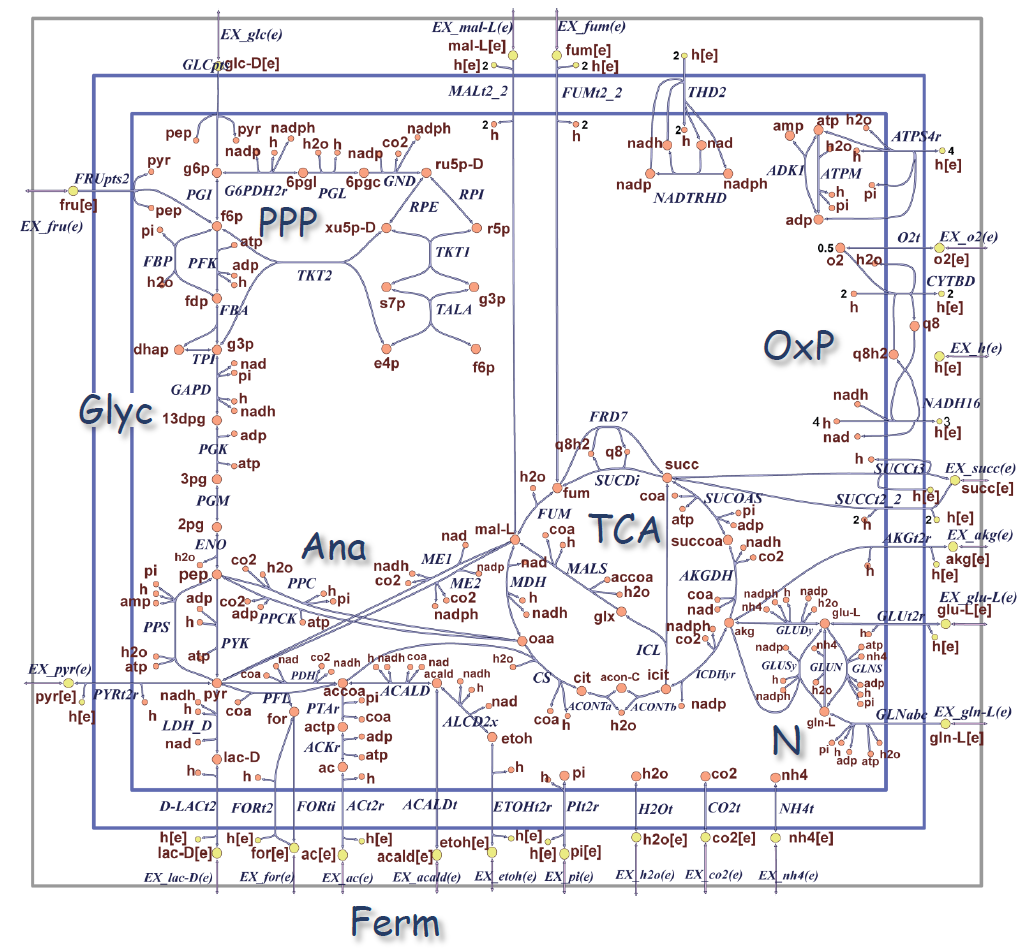

**                                                                                                    Figure 1**. Metabolic map of the *E.coli* core model [3].

A metabolic reconstruction consists of a collection of genes, reactions which represent proteins (enzymes), metabolites, a stochiometric matrix that defines the relationship between the reactions and metabolites, reaction constraints, and a biomass function. The genes in the model are represented by gene name and genomic locus. Metabolites are represented with lowercase characters and typically have a suffix that represents the compartment they operate in. For the simplified  *E.coli *core model there are only two compartments represented; cytosolic metabolites with the suffix "[c]" and extracellular metabolites with the suffix "[e]." To keep this model simple, the *E.coli* core model does not distinguish between the periplasmic space and the extracellular medium. The COBRA model's representation of metabolites includes an abbreviation, the official name, the chemical fomula, and the charge of the metabolite. 

Reactions in the COBRA models correspond to the enzymes in a cell and are represented by uppercase abbreviations, an offical name,  and a stochiometric formula.The suffixes used in the reaction abbreviations, include; 'i' (irreversible), 'r' (reversible), 'abc' (ATP-Binding Cassette transporter), and 't' (transport). Most of the reactions used in the model are named after the enzymes that catalyze them. As an example, ENO represents the enzyme "enolase" and includes the formula "2pg[c]  <=> h2o[c] + pep[c] ."  A special type of reaction found in COBRA models are exchange reactions which have the form of  "EX_xxx(e)" and are used to secrete/uptake metabolites to/from the extracellular space. As an example, the exchange reaction for glucose is "EX_glc(e)."

The COBRA models also include Boolean rules for each reaction describing the gene-reaction relationship. For example, ‘gene1 and gene2’ indicate that the two gene products are part of an enzyme whereas ‘gene1 or gene2’ indicate that the two gene products are isozymes that catalyze the same reaction.The gene-protein-reaction associations (GPRA) for a few reactions are shown in Figure 2. Each GPRA is composed of a gene locus, a translated peptide (mRNA), and functional proteins that work together to make a single reaction (enzyme). At the top of each GPRA is a portion of the genomic context that is highlighted. Genes in this figure are designated by their locus name and represented by light blue boxes. The translated peptides are represented by the purple boxes, the functional proteins are represented by red ovals, while the reactions are labeled dark blue boxes. As can be seen in the figure, isozymes include two different proteins that are connected to the same reaction. For the case of proteins with multiple peptide subunits, the peptides are connected with an '&' sign above the protein. For complexes of many functional proteins, the proteins are also connected with an '&' sign above the reaction. Certain genes that are responsibible for the creation of a given reaction, such as pykF and pykA, can be encoded by genes in operons that are widely separated on the genome. In this figure operons are represented by shaded rectangles around one or more genes. Genes are represented by rectangles with one side pointed to denote the direction of the sense strand. Other operons can contain multiple genes which encode protein subunits into larger proteins. As an example, the same sdhCDAB-sucABCD operon that codes for the SUCDi proteins also codes for two proteins of the 2-oxoglutarate dehydrogenase enzyme complex, AKGDH.

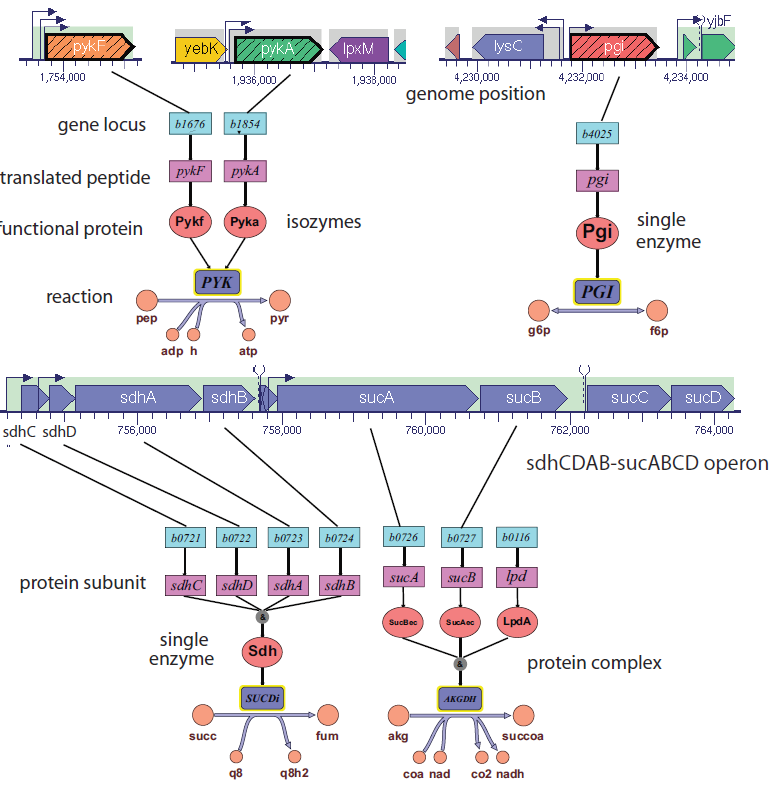

**                                                                            Figure 2.** Examples of the gene-protein-reaction associations from the* E. coli *core model [3].

Now let's start to use the COBRA toolbox to begin exploring the *E.coli *core model. The first thing that needs to be done is to load the model into the Matlab work environment. This can be achieved by loading the Matlab version of the model (.mat) into Matlab. This model is available in the downloaded COBRA toolbox software. *[Timing: Seconds]*

global CBTDIR
model = readCbModel([CBTDIR filesep 'test' filesep 'models' filesep 'mat' filesep 'ecoli_core_model.mat']);
e_coli_core = model; % Save the original model for later use

After you load the *E.coli* core model into the Matlab, you should be able to look at the MATLAB workplace and see that the model is loaded as shown in Figure 3.

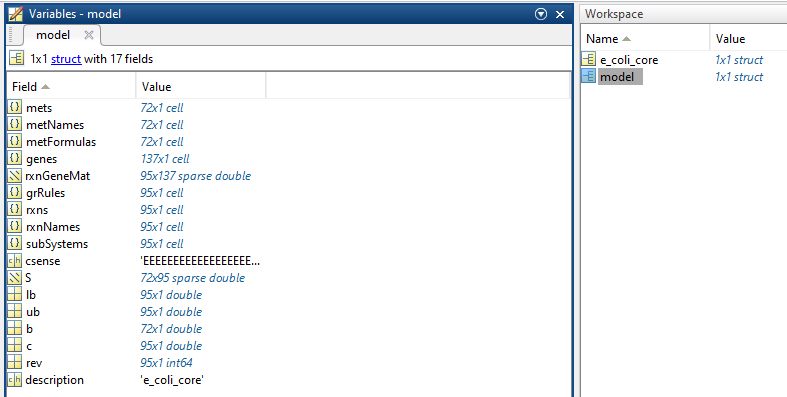

**                                                                            Figure 3.** Matlab workspace after the* E.coli* core model has been loaded into Matlab.

Perhaps the easiest way to access all the information in the COBRA model is to print out a spreadsheet that contains all the information stored in the model. This can be accomplished using the "writeCbModel" function. *[Timing: Seconds]*

outmodel = writeCbModel(model, 'xls', 'core_model.xls')

This function will write the model to an Excel spreadsheet named "core_model.xls" and allow you to explore all the details associated with both the model reactions and metabolites. This is illustrated in Figure 4. You can also gain specific information on genes, reactions, metabolites and GPRA's using COBRA Toolbox functions. This will be shown later in this tutorial.

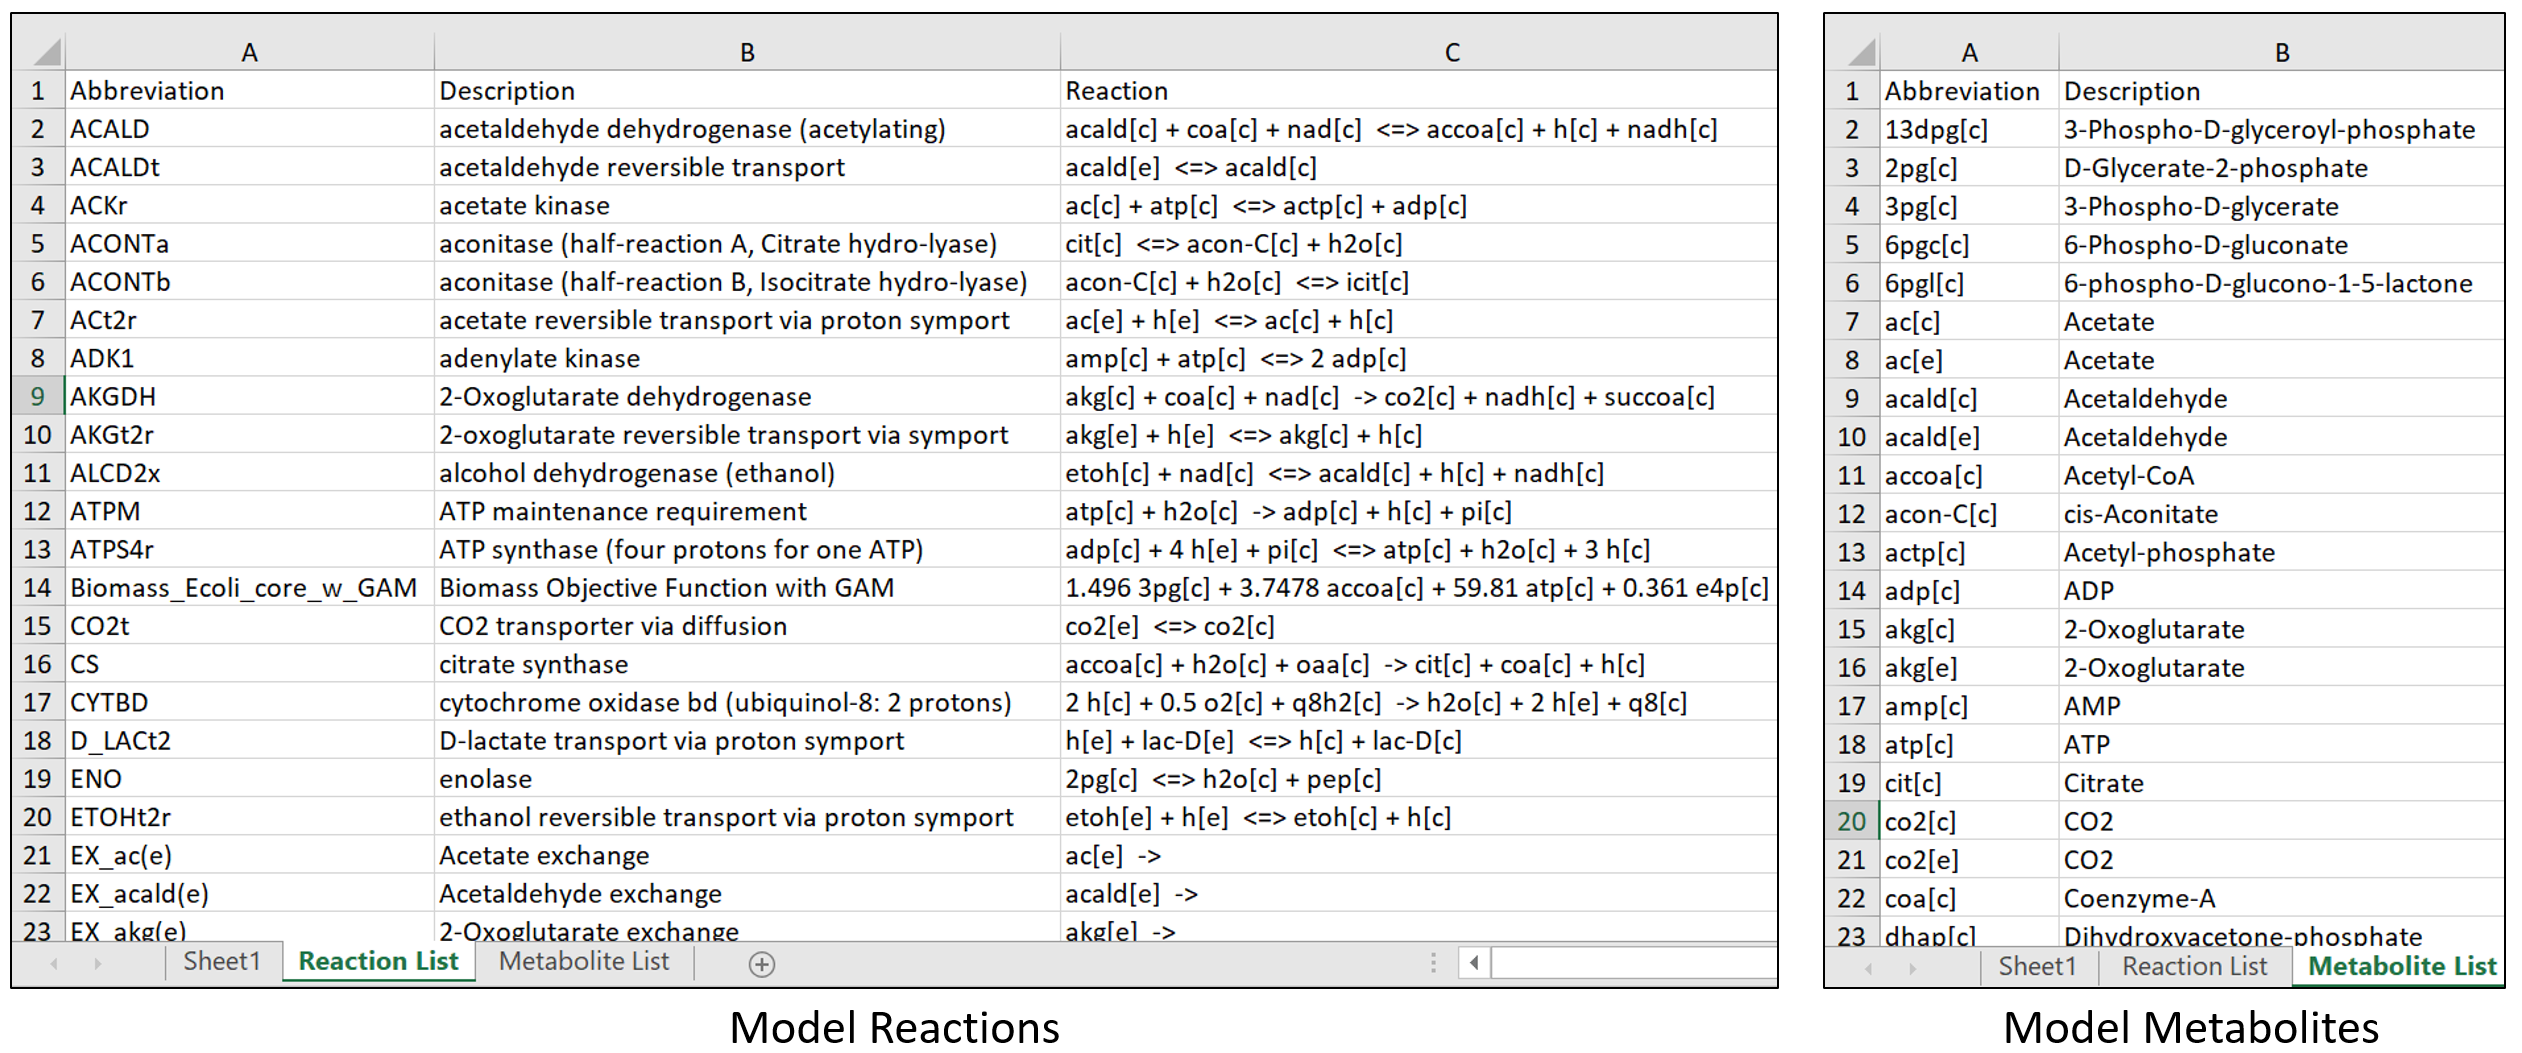

**                                        Figure 4. **Screenshot of "core_model.xls" showing a portion of the spreadsheet with both reactions and metabolites of the model.

One way to understand how the cell is operating is to visiualize the cell operation through a metabolic map. There are maps available in the COBRA toolbox installation for several different organisms that can be used to visualize the models and also overlay calculated flux values on the map (we will discuss this in the flux balance analysis section). To create a map requires a special file referred to as an "exportmap."  For the case of the *E.coli* core model the exportmap is called the "ecoli_core_map.txt" and is included with the default COBRA toolbox installation. The following steps can be used to create a map of the *E.coli* core in an "SVG" file called "target.svg." This map file should be located in your working directory. *[Timing: Seconds]*

map=readCbMap('ecoli_core_map.txt');

Each model.subSystems{x} is a character array, and this format is retained.


options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawCbMap(map);

Figure 5 is a screenshot of  the *E.coli* core map produced by  "drawflux".

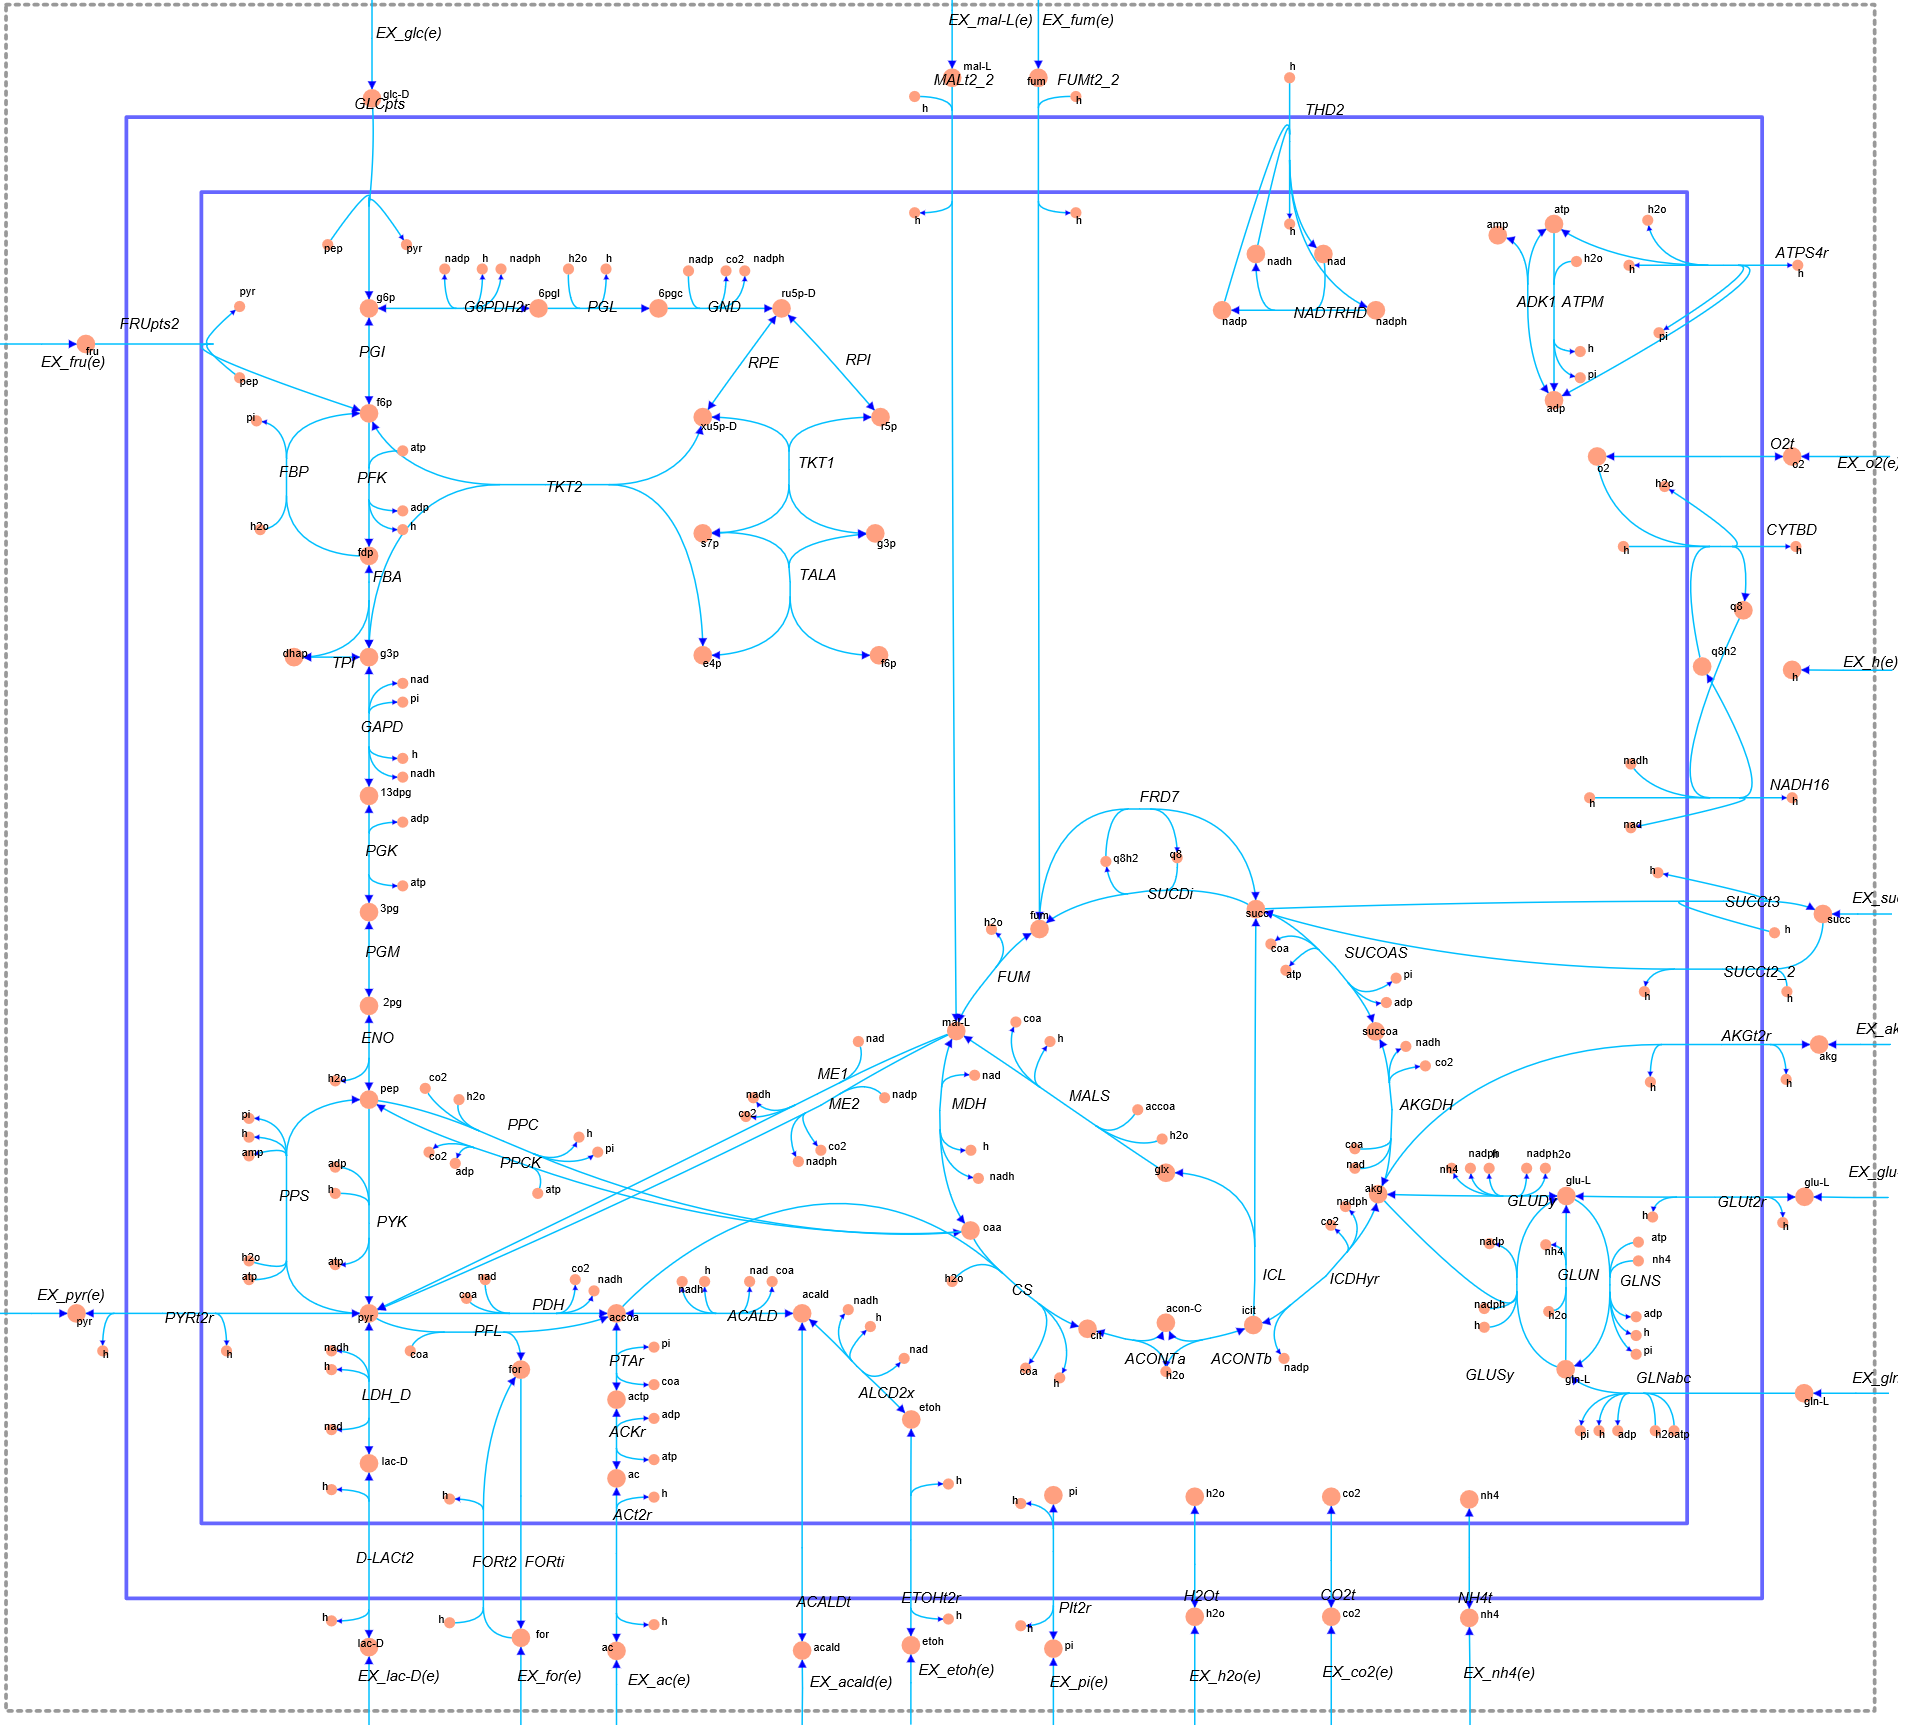

                                                                                   **Figure 5.** The screenshot of a "drawflux" produced *E.coli *core model map.

This SVG map can be read with most browsers and is very easy to use to search and explore the *E.coli *network.

**2.A. Genes** 

Now let's begin by exploring some of the Matlab code and COBRA toolbox functions that can be used to extract information about the genes from the model. Below are a collection of COBRA Toolbox functions that retrieve key information from the genes in the model. The genes are only represented by their gene locus number (e.g. b2097). The gene name can be achieved with a quick search of the EcoCyc website (https://www.ecocyc.org/). To start with, the genes included in the model and their geneIDs are stored in the "model.genes" structure. The "findGeneIDs"  COBRA Toolbox function can be used to pull the geneID from the model structure.  The first 10 genes in the model, and their geneIDs, can be printed out as follows. *[Timing: Seconds]*

genes = cellstr(model.genes(1:10));

Each model.subSystems{x} is a character array, and this format is retained.


outmodel = struct with fields:
              S: [72×95 double]
              b: [72×1 double]
              c: [95×1 double]
         csense: [72×1 char]
    description: 'ecoli_core_model.mat'
          genes: {137×1 cell}
        grRules: {95×1 cell}
             lb: [95×1 double]
    metFormulas: {72×1 cell}
       metNames: {72×1 cell}
           mets: {72×1 cell}
        modelID: 'model'
      osenseStr: 'max'
          rules: {95×1 cell}
     rxnGeneMat: [95×137 double]
       rxnNames: {95×1 cell}
           rxns: {95×1 cell}
     subSystems: {95×1 cell}
             ub: [95×1 double]


geneIDs = findGeneIDs(model, model.genes(1:10));
printLabeledData(model.genes(1:10),geneIDs)

For the case of finding a single geneID from the model, the gene locus number needs to be included in single quotes, such as 'b_number '. *[Timing: Seconds]*

findGeneIDs(model, 'b0116')

Now, to find the reactions that are associated with a given gene, you can use the "findRxnsFromGenes" function as shown below. *[Timing: Seconds]*

[results ListResults]=findRxnsFromGenes(model,'b0116',0,1)


This result shows that the gene "b0116" is associated with the two reactions AKGDH and PDH. 

**2.B. Reactions**

Reactions and their rxnIDs are stored in the "model.rxns" structure with the reaction names being stored in "model.rxnNames." The COBRA Toolbox function "findRxnIDs" can be used to extract the rxnID from the model structure.  Note that the biomass function "Biomass_Ecoli_core_w_GAM" is listed as one of the reactions. *[Timing: Seconds]*

rxnIDs = findRxnIDs(model, model.rxns(1:15));

Document Written


printLabeledData(model.rxns(1:15),rxnIDs)

To find a single rxnID from the model use the "findRxnIDs"  with the desired reaction abbreviation included in single quotes, e.g. 'ENO'. *[Timing: Seconds]*

rxnIDs = findRxnIDs(model, 'ENO')

Finding the name of the 'ENO' reaction can be recovered using the "model.rxnNames" structure with the desired reaction rxnID. *[Timing: Seconds]*

model.rxnNames(rxnIDs)

To find the formula of the reaction, use the "printRxnFormula" function. *[Timing: Seconds]*

printRxnFormula(model,'ENO');

b0008               	           1
b0114               	           2
b0115               	           3
b0116               	           4
b0118               	           5
b0351               	           6
b0356               	           7
b0451               	           8
b0474               	           9
b0485               	          10


To find the genes that are associated with a given reaction, you can use the "findGenesRxns" function. *[Timing: Seconds]*

[geneList]=findGenesFromRxns(model,'ENO');

ans = 4

geneList{1:1}

Finally, there are times when it is ncessary to find all the "reactant" metabolites that feed a reaction as well as all the "product" metabolites that are produced by the reaction. This can be achieved using the "surfNet" function as shown below (there is a COBRA tutorial on this by Siu Hung Joshua Chan called "Browse Networks in the Matlab Command Window Using surfNet"). This functions output includes a listing of the reactants and products based on the reaction formulas. It should be pointed out that in situations where a reaction becomes reversible, a metabolite that is a reactant could become a product and a metabolite that is a product could become a reactant. *[Timing: Seconds]*

surfNet(model, 'GAPD')

results = struct with fields:
    gene_b0116: {2×4 cell}


ListResults = 2×5 cell array
    {'AKGDH'}    {'akg[c] + coa[c] + nad[c]  -> co2[c] + nadh[c] + succoa[c] '}    {'Citric Acid Cycle'         }    {'2-Oxoglutarate dehydrogenase'}    {'gene_b0116'}
    {'PDH'  }    {'coa[c] + nad[c] + pyr[c]  -> accoa[c] + co2[c] + nadh[c] ' }    {'Glycolysis/Gluconeogenesis'}    {'pyruvate dehydrogenase'      }    {'gene_b0116'}


In this case, the "reactant" metabolites for the GAPD reaction are g3p[c], nad[c] and pi[c] while the "product" metabolites are 13dpg[c], h[c], and nadh[c].

**2.C. Metabolites**

The metabolites included in the model and their metabolite IDs (metIDs) are stored in the "model.mets" structure with the metabolite names being stored in model.metNames. The COBRA Toolbox function "findMetIDs" can be used to extract the metID's from the model structure as shown in the following example.  *[Timing: Seconds]*

metIDs = findMetIDs(model, model.mets(1:15));
printLabeledData(model.mets(1:15),metIDs)

ACALD               	           1
ACALDt              	           2
ACKr                	           3
ACONTa              	           4
ACONTb              	           5
ACt2r               	           6
ADK1                	           7
AKGDH               	           8
AKGt2r              	           9
ALCD2x              	          10
ATPM                	          11
ATPS4r              	          12
Biomass_Ecoli_core_w_GAM	          13
CO2t                	          14
CS                  	          15


To find a single metID from the model use the "findMetIDs"  with the desired metabolite abbreviation included in single quotes, e.g. 'akg[c]'. *[Timing: Seconds]*

metIDs = findMetIDs(model, 'akg[c]')

rxnIDs = 18

Finding the name of the 'akg[c]' reaction yeilds *[Timing: Seconds]*

model.metNames(metIDs)

ans = 1×1 cell array
    {'enolase'}


To find the chemical formula of the metabolite you can use the "model.metFormulas" structure with a metID. *[Timing: Seconds]*

model.metFormulas(metIDs)

ENO	2pg[c] 	<=>	h2o[c] + pep[c] 


Finally, to find reactions that both produce and consume a desired metabolite you can again use the "surfNet" function. This includes a listing of the consuming and producing reactions based on the reaction formulas. In some situations, if a reaction is reversible, the producing/consuming reactions could be switched. *[Timing: Seconds]*

surfNet(model, 'atp[c]')

As you would expect, there should be a large number of consumers of atp[c] but only a small number of producers.

**2.D. Gene-Protein-Reaction Associations**

A gene-protein-reaction association (GPRA) shows the Boolean relationship between the genes that are required to produce a specific reaction (see Figure 2). The Boolean relationship between the genes and a given reaction can be found using the "model.grRules" structure of the model. This is shown below. *[Timing: Seconds]*

rxnIDs = findRxnIDs(model, 'PYK');

ans = 1×1 cell array
    {'b2779'}


model.grRules(rxnIDs)

Here is an example of a more complicated gene-reaction relationship. *[Timing: Seconds]*

rxnIDs = findRxnIDs(model, 'ATPS4r');


Rxn #49  GAPD, Bd: -1000 / 1000, glyceraldehyde-3-phosphate dehydrogenase, grRules: b1779
g3p[c] + nad[c] + pi[c]   <=>   13dpg[c] + h[c] + nadh[c] 
  id   Met       Stoich     metNames, metFormulas
Reactant:
 #33     g3p[c]  -1         Glyceraldehyde-3-phosphate, C3H5O6P
 #50     nad[c]  -1         Nicotinamide-ad

model.grRules(rxnIDs)

**2.E. Model Constraints** 

In constraint-based simulations, the system constraints are implemented in two ways in COBRA models: 1) as reaction formulas that balance reaction input and output metabolites (mass balance), and 2) as inequalities that impose upper and lower bounds on the flux rates of every reaction in the model. To set these constraints, every reaction is given both upper and lower bounds, which define the maximum and minimum allowable fluxes through the reactions.   

To find the constraints for all the reactions in the model, the COBRA Toolbox provides the "printConstraints(model,lb, ub)" function where the "lb" value is the lower bound of the reactions potential flux while "ub" refers to the upper bound of the reactions flux. It is important to understand the default constraint settings for the *E.coli* core model. In this model all reversible reactions in the cytoplasm are initally set so that their lower bound is -1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$with an upper bound of +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. On the other hand, irreversible reactions, except ATPM, are set with a lower bound of 0 and an upper bound of +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. The ATP maintenance reaction (ATPM) is set with a lower bound of 0 and an upper bound of +8.39 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$(this will be discussed later). All the exchange reactions, except EX_glc(e), are set to allow secretion but not uptake, thus a lower bound of 0 and an upper bound of +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. To avoid confusion, it should be understood that all exchange reactions, which are reactions that interface between the extracellular and cytoplasmic space, assume that secretion is positive while uptake is labeled negative.  Finally, the glucose exchange reaction, EX_glc(e), is set with a lower bound of -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ and an upper bound of +1000 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$.

To see the constraints for the reactions that are not set at the minimum/maximum (-100\100) values, then "lb" and "ub" can be adjusted. *[Timing: Seconds]*

printConstraints(model,-1001, +1001)

Note that the exchange reaction that controls the uptake of glucose, 'EX_glc(e) is automatically set to -10 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$. 

The results of the upper or lower bounds for a particular reaction can be found by using the COBRA model structure, "model.lb" for the lower bound and "model.ub" for the upper bound. *[Timing: Seconds]*

rxnIDs = findRxnIDs(model,'EX_glc(e)');

13dpg[c]            	           1
2pg[c]              	           2
3pg[c]              	           3
6pgc[c]             	           4
6pgl[c]             	           5
ac[c]               	           6
ac[e]               	           7
acald[c]            	           8
acald[e]            	           9
accoa[c]            	          10
acon-C[c]           	          11
actp[c]             	          12
adp[c]              	          13
akg[c]              	          14
akg[e]              	          15


model.lb(rxnIDs)
model.ub(rxnIDs)

metIDs = 14

Altering the constraints for a reaction can be accomplished with the "model = changeRxnBounds(model,rxnNameList,value,boundType)" function. For this function the second parameter is the reaction(s) that need to be constrained, the third parameter is the desired flux rate in $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$, and the fourth parameter can be 'u' - upper limit, 'l' - lower limit, or 'b' - both (Default = 'b'). *[Timing: Seconds]*

model = changeRxnBounds(model,'EX_glc(e)',-5,'l');

ans = 1×1 cell array
    {'2-Oxoglutarate'}


printConstraints(model,-1001, +1001); % Showing the result of the change

You can now see that the lower bound for glucose has been changed to -5 $\textrm{mmol}\cdot {\textrm{gDW}}^{-1} \cdot {\textrm{hr}}^{-1}$ .

**2.F. Objective Functions**

In order to perform flux balance analysis it is necessary to define a biological objective or objective function. For the case of predicting growth, the biological objective is the biomass production or the rate at which metabolic compounds are converted into biomass constituents. This biomass production is mathematically represented by the addition to the model of an artificial ‘biomass reaction’ (Biomass_Ecoli_core_w_GAM) which consumes precursor metabolites at stoichiometries that simulate biomass production. The precursors for the *E.coli *core model are shown in Figure 6. 

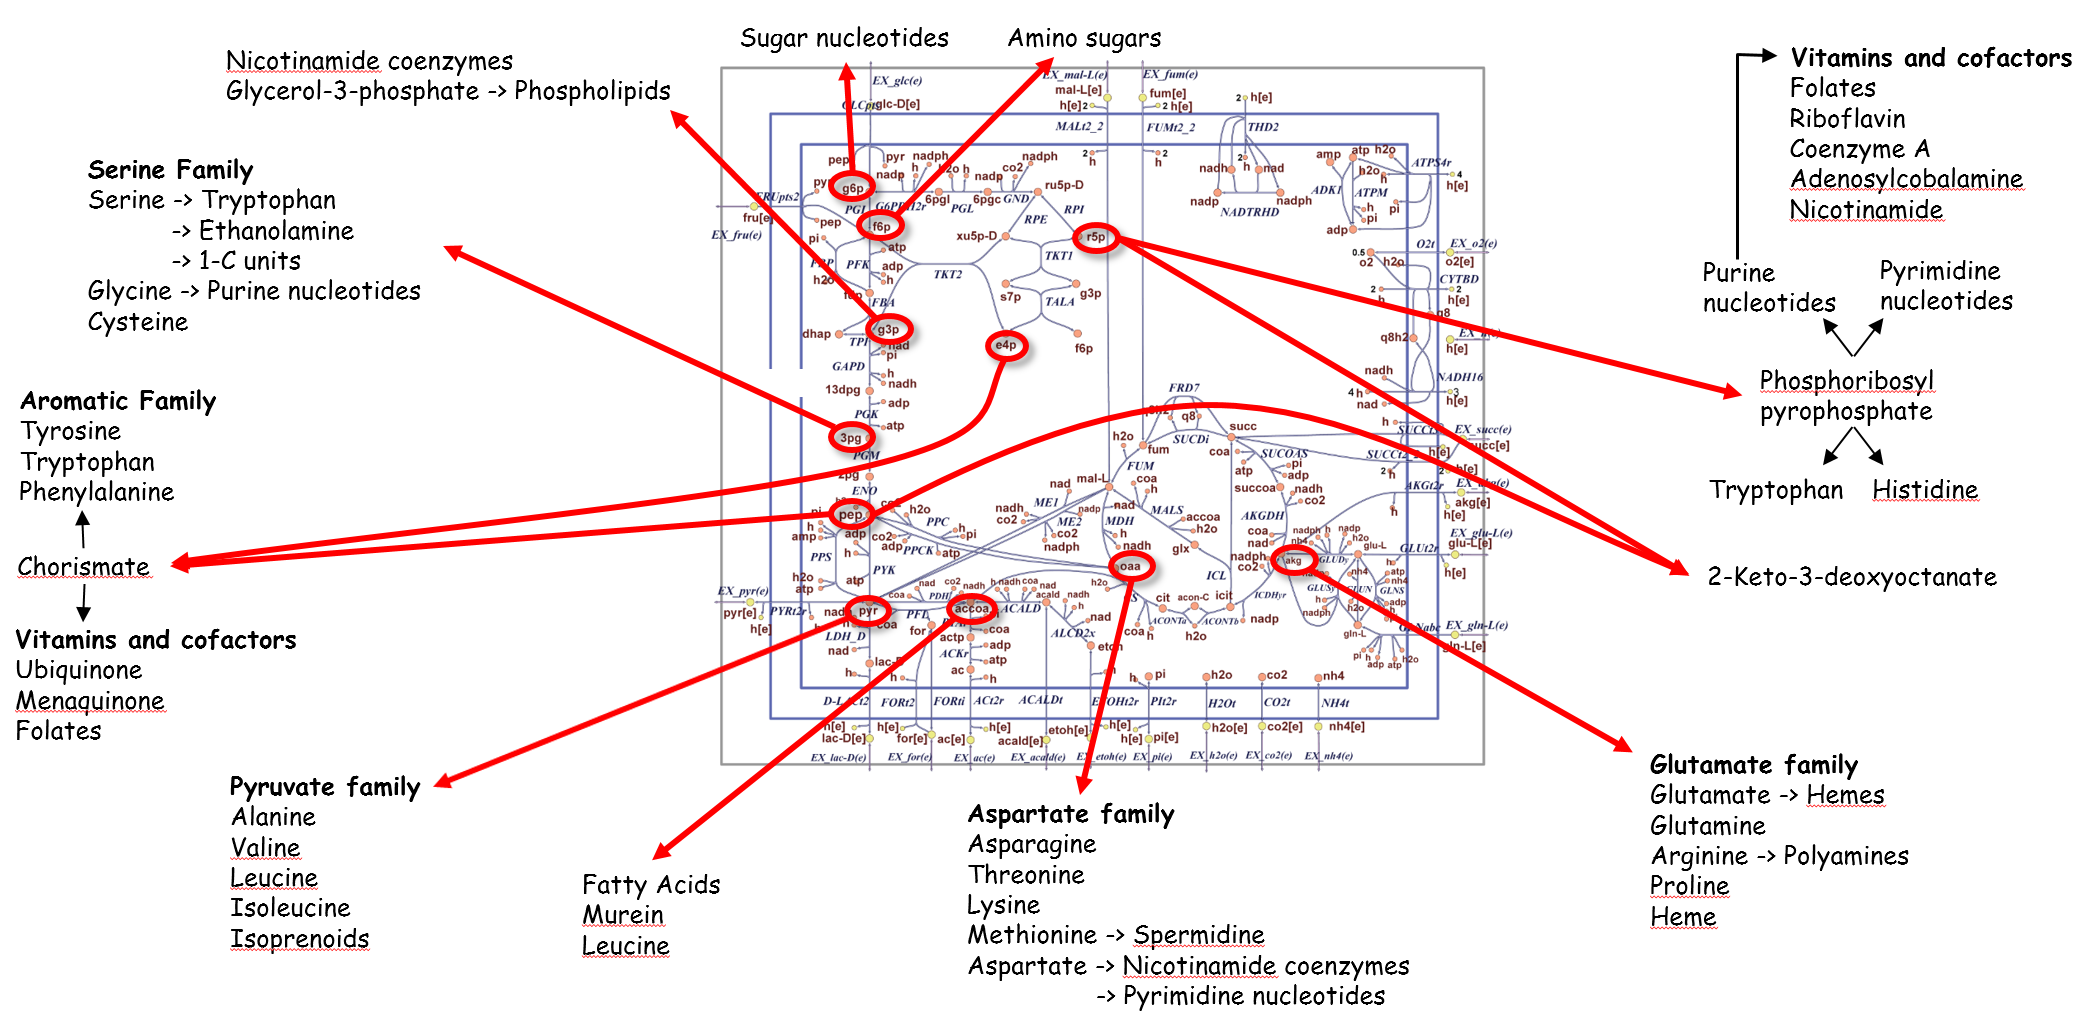

**                                                                                                                Figure 6.** *E.coli* core model precursors [11].

The biomass reaction also includes key cofactors (atp[c], adp[c], nad[c], nadh[c], nadph[c], and pi[c])  that are required for cell growth and operation. The biomass reaction is based on experimental measurements of biomass components allowing the reaction to be scaled so that its flux is equal to the exponential growth-rate (μ) of the organism. With the biomass now represented in the model, the maximum growth rate can be predicted by calculating the conditions that maximize the flux through the biomass reaction.  

The biomass reaction and the weighted precursor metaboites can be inspected by printing out the formula for the biomass function using the "printRxnFormula" COBRA Toolbox function. *[Timing: Seconds]*

printRxnFormula(model,'Biomass_Ecoli_core_w_GAM')

ans = 1×1 cell array
    {'C5H4O5'}


The objective function can also be checked using the "checkObjective(model)" function which will print out the stoichiometric coefficients for each metabolite along with the name of the objective. *[Timing: Seconds]*

checkObjective(model)


Met #17  atp[c], ATP, C10H12N5O13P3

Consuming reactions:
  #3  ACKr, Bd: -1000 / 1000, acetate kinase, grRules: (b3115 or b2296 or b1849)
ac[c] + atp[c]   <=>   actp[c] + adp[c] 
  #7  ADK1, Bd: -1000 / 1000, adenylate kinase, grRules: b0474
<a h

The objective function for the *E.coli* core model is automatically set to be the biomass reaction. Setting the biomass function to be the objective function can also be done using the model = changeObjective(model,'reaction name'') as shown below. *[Timing: Seconds]*

model = changeObjective(model,'Biomass_Ecoli_core_w_GAM');

ans = 1×1 cell array
    {'(b1854 or b1676)'}


ans = 1×1 cell array
    {'(((b3736 and b3737 and b3738) and (b3731 and b3732 and b3733 and b3734 and b3735)) or ((b3736 and b3737 and b3738) and (b3731 and b3732 and b3733 and b3734 and b3735) and b3739))'}


No closed reactions with non-default constraints.
...forward reactions with non-[-1001, 1001] constraints:
          Forward_Reaction                                   Name                               lb      ub                                                                                                                                                                                          equation                                                                                                                                                                                     
    ____________________________    _______________________________________________________    ____    ____    ___________________________________________________________________________________________________________________________________________

ans = -10

ans = 1000

No closed reactions with non-default constraints.
...forward reactions with non-[-1001, 1001] constraints:
          Forward_Reaction                                   Name                               lb      ub                                                                                                                                                                                          equation                                                                                                                                                                                     
    ____________________________    _______________________________________________________    ____    ____    ___________________________________________________________________________________________________________________________________________

Biomass_Ecoli_core_w_GAM	1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] + 0.205 g6p[c] + 0.2557 gln-L[c] + 4.9414 glu-L[c] + 59.81 h2o[c] + 3.547 nad[c] + 13.0279 nadph[c] + 1.7867 oaa[c] + 0.5191 pep[c] + 2.8328 pyr[c] + 0.8977 r5p[c] 	->	59.81 adp[c] + 4.1182 akg[c] + 3.7478 coa[c] + 59.81 h[c] + 3.547 nadh[c] + 13.0279 nadp[c] + 59.81 pi[c] 


ans = 1×1 cell array
    {'1.496 3pg[c] + 3.7478 accoa[c] + 59.81 atp[c] + 0.361 e4p[c] + 0.0709 f6p[c] + 0.129 g3p[c] + 0.205 g6p[c] + 0.2557 gln-L[c] + 4.9414 glu-L[c] + 59.81 h2o[c] + 3.547 nad[c] + 13.0279 nadph[c] + 1.7867 oaa[c] + 0.5191 pep[c] + 2.8328 pyr[c] + 0.8977 r5p[c]  -> 59.81 adp[c] + 4.1182 akg[c] + 3.7478 coa[c] + 59.81 h[c] + 3.547 nadh[c] + 13.0279 nadp[c] + 59.81 pi[c] '}


summaryT = 23×5 table
    Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

       -1.496       3pg[c]         3      Biomass_Ecoli_core_w_GAM     13  
      -3.7478       accoa[c]      10      Biomass_Ecoli_core_w_GAM     13  
        59.81       adp[c]        13      Biomass_Ecoli_core_w_GAM     13  
       4.1182       akg[c]        14      Biomass_Ecoli_core_w_GAM     13  
       -59.81       atp[c]        17      Biomass_Ecoli_core_w_GAM     13  
       3.7478       coa[c]        21      Biomass_Ecoli_core_w_GAM     13  
       -0.361       e4p[c]        23      Biomass_Ecoli_core_w_GAM     13  
      -0.0709       f6p[c]        26      Biomass_Ecoli_core_w_GAM     13  
       -0.129       g3p[c]        33      Bioma

ans = 1×1 cell array
    {'Biomass_Ecoli_core_w_GAM'}
